#### BME Vanderbilt University

#### Professor Mark D. Does

# MATLAB Bootcamp, Part 3, updated 12/2021

clear all
close all
clc

## Displaying data -- plots and graphs.

MATLAB has a plethora of tools for visualizing data. I'll show you a few here.

### Discrete data

First, note that any data we plot in MATLAB is discrete, but in some cases we have sampled a signal so densely in the independent variable domain (often time or space) that we can consider it continuous. For now, consider the example of measuring someone's height as a function of age in years. This is just made-up example data, so I'll enter it manually 

t = (1:18)'; % age in years, arranged in a column vector
h = [76.2, 86.9, 89.7, 99.0, 107.1, 113.3, 115.8, 127.0, 132.3, 137.9, ...
  151.1, 160.5, 168.2, 172.3, 174.4, 178.8, 180.0 180.2]';
% height in cm, arranged in a column vector

Now let's plot the data. The first rule of data-club is that you don't *talk* about data, you *look* at data. That is, whenever possible, look at your data before, during, and after analysis. You'd be suprised how often a simple visual evaluation will reveal a problem or explain an outcome.

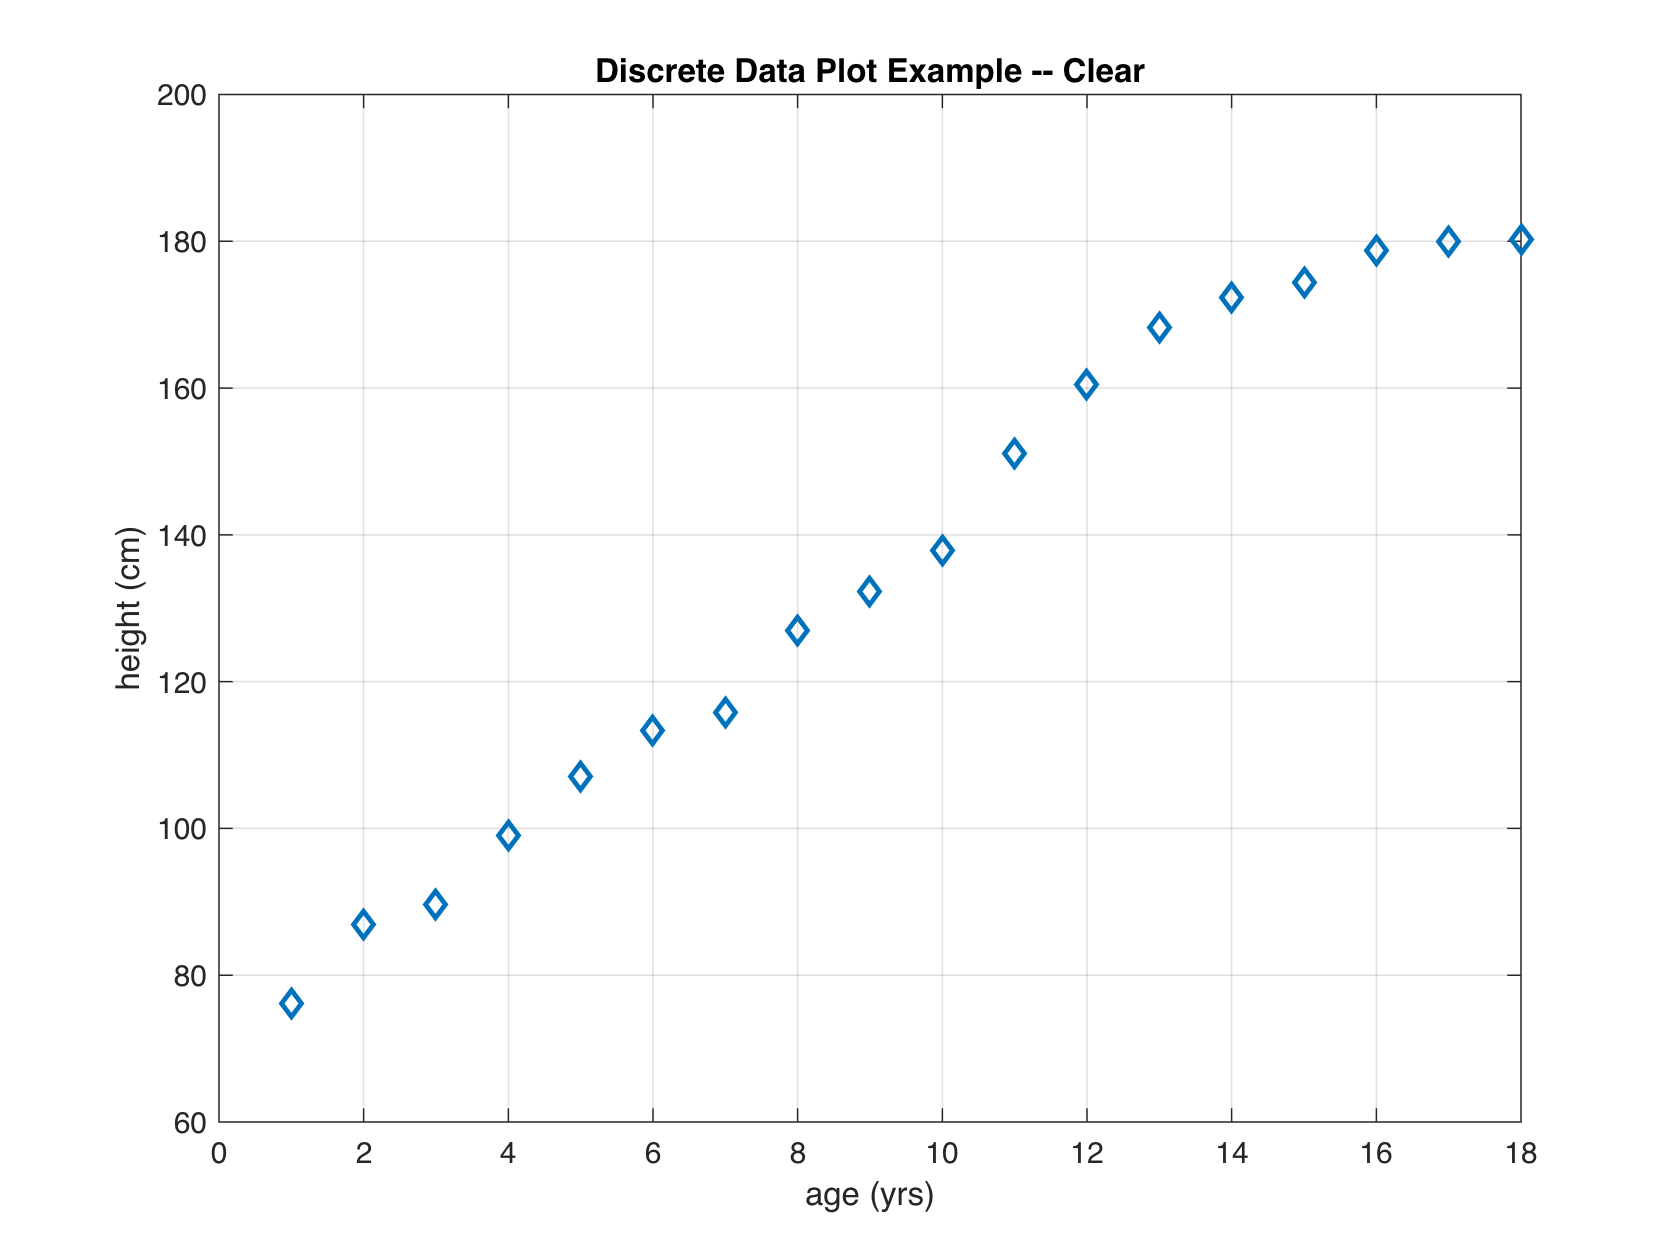

plot(t,h,'d') % plot the data as discrete points. The scatter function works here too
% Note that we use the 'd' option to indicate diamond markers for each data
% point. See the help on 'plot' for other options

xlabel('age (yrs)') % always label axes!
ylabel('height (cm)') % always label axes!
title('Discrete Data Plot Example -- Clear')

figure 

If you're using .m code, `figure` creates a new figure window, without which the next `plot` call will overwrite the previous figure window. With Live Editor, this isn't needed, but I think it's a good practice.

If you want a line connecting these discrete points, to help the eye follow the data, that's OK

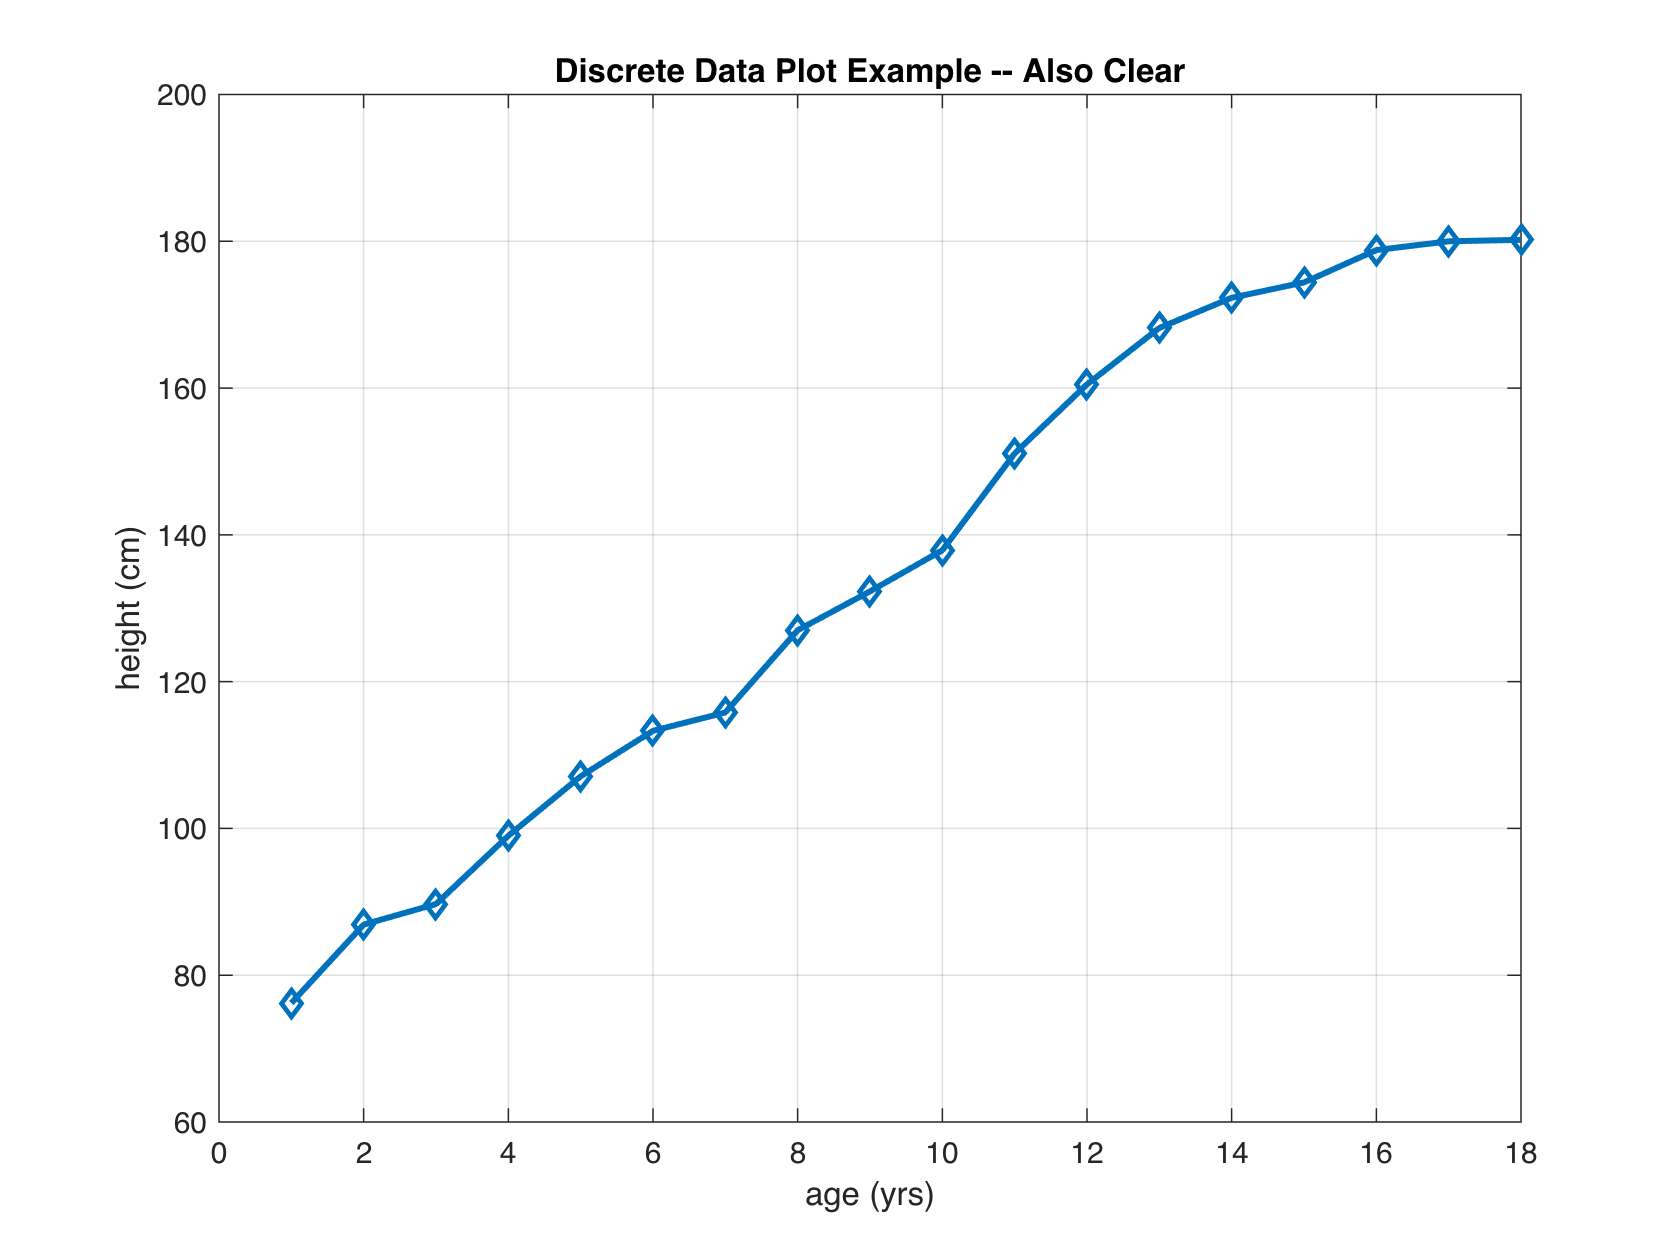

plot(t,h,'d-')
% Note that we use the '-' option to indicate a solid line. 
% See the help on 'plot' for other options
xlabel('age (yrs)') % always labe axes!
ylabel('height (cm)') % always labe axes!
title('Discrete Data Plot Example -- Also Clear')

But, if you just plot these data with a line graph, you imply that you have information about this person's height at times between the samples. Avoid this.

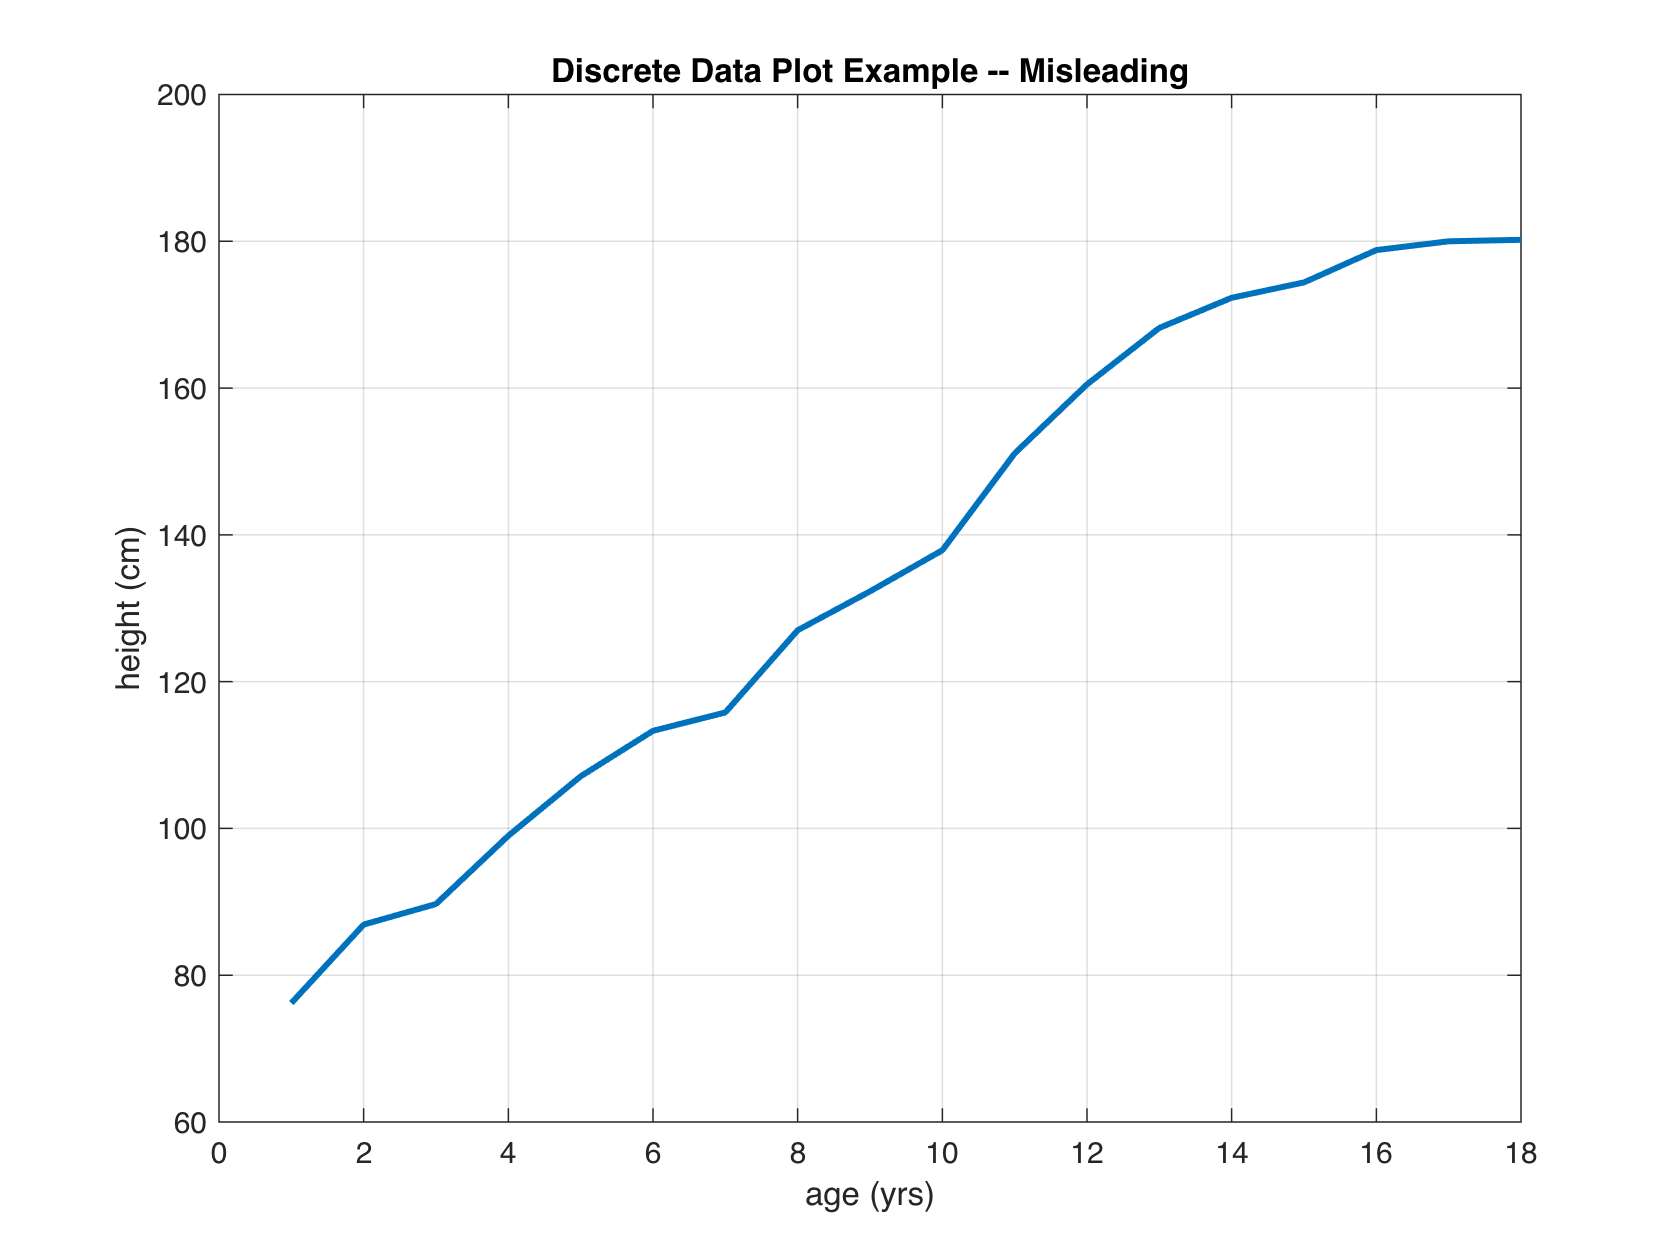

figure
plot(t,h,'-')
% Note that we use the 'd' option to indicate diamond markers for each data
% point. See the help on 'plot' for other options
xlabel('age (yrs)') % always labe axes!
ylabel('height (cm)') % always labe axes!
title('Discrete Data Plot Example -- Misleading')

Perhaps you have fitted these data to a simple function (we'll discuss how to do this later in the course) and you want to plot the fitted curve over the data. This is also fine and MATLAB will default to making the observed and fitted data different color. I'll use a 2nd order polynomial for this example, but that is probably not the best choice to model growth.

p = polyfit(t,h,2); % built in MATLAB function for fitting a polynomial. 
% I'm using polyfit here b/c it's easy to appreciate what it's doing, but
% in this class, you will do this analysis using matrix algebra
h_model = polyval(p,t); % compute the fitted line -- predicted height vs age.
figure
plot(t,h,'d',t,h_model)

Note that we can plot two sets of data with one call of the `plot` function. Alternatively, we can use the `hold` function, to freeze current data in the figure and then call the `plot` function again to add the second set of data.

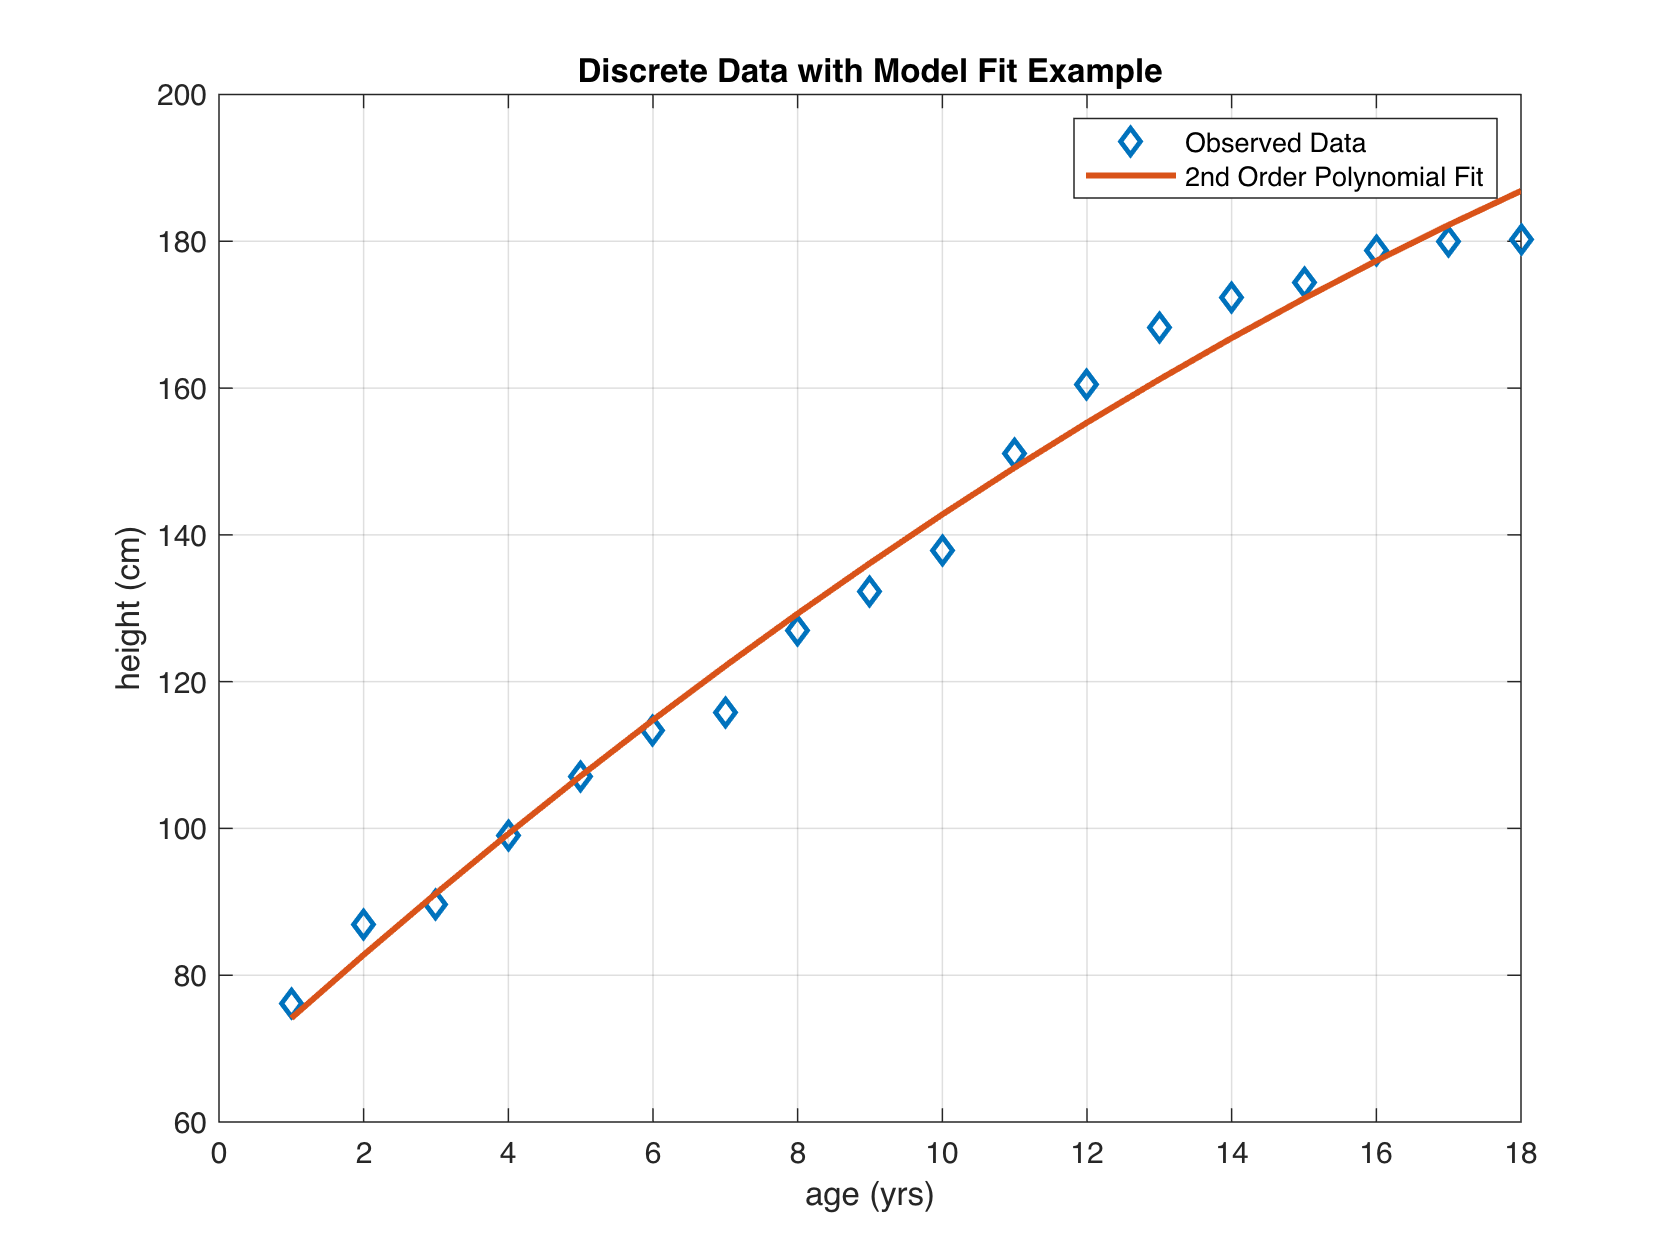

xlabel('age (yrs)') % always label axes!
ylabel('height (cm)') % always label axes!
title('Discrete Data with Model Fit Example')
legend('Observed Data','2nd Order Polynomial Fit')

% The 'legend' function creates labels for data in the order that they
% were plotted. 

Note that the `scatter` function works similarly to the `plot` function, as used above, except that is allows you to independently change the size and/or color of each data marker -- look up `scatter` for more information.

### Error Bars

*All measured data have uncertainty.* 

When you report data, you **must** report its uncertainty in some meaningful way. In the preceeding example, it is likely that the precision of the height measurement was around 1 mm (0.1 cm). If this were the case, it would be sufficient to report this in the figure caption or state that the standard error in the measurements was smaller than the size of the data markers (i.e., the diamonds). However, in many cases the uncertainty in the data is much greater. For the preceeding example, let's imagine that the person's height was estimated by eye from a distance such that the standard error in the measurement was 3 cm. In this case, you should report this error on the figure. 

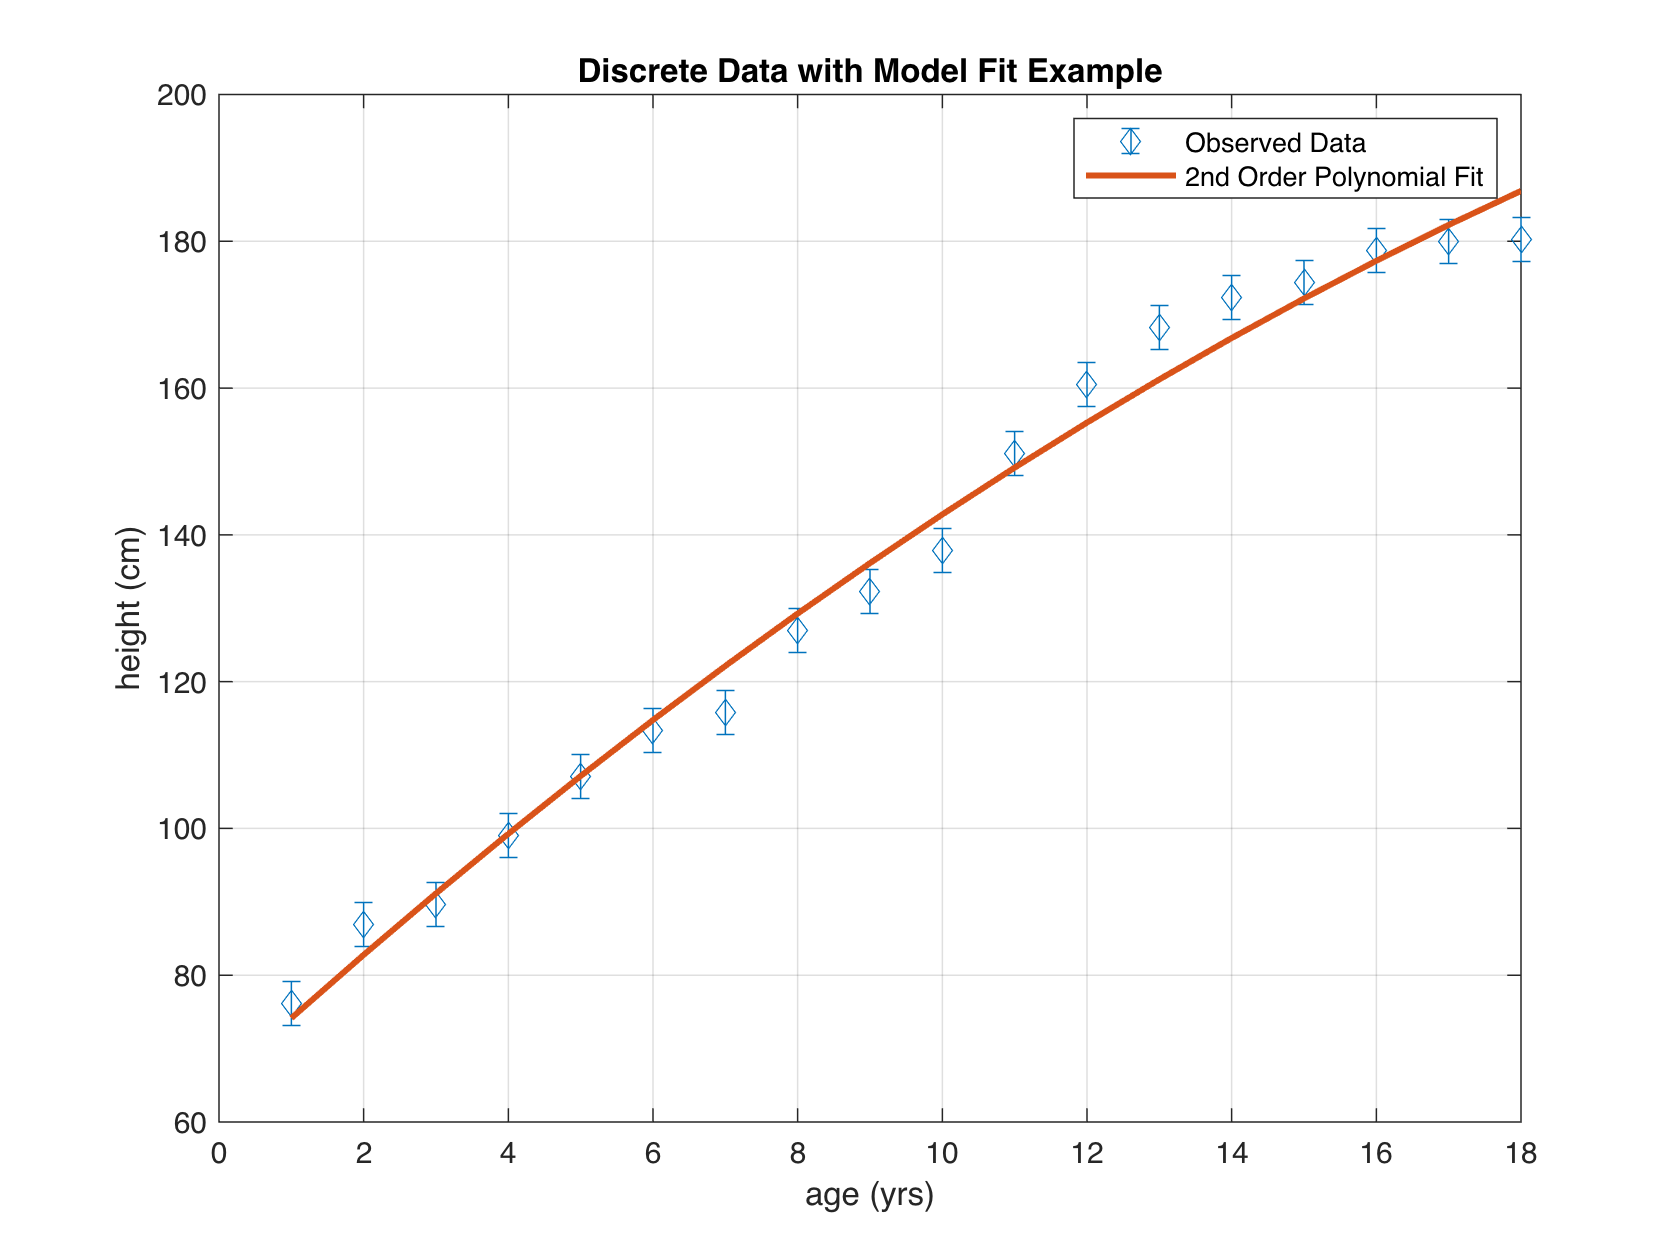

figure
height_SE = 3; % standard error of the height measurements
errorbar(t,h,height_SE*ones(size(h)),'d')
hold on 
% 'hold on' freezes objects on the current figure, allowing you to add more
% objects without erasing the previous ones

plot(t,h_model) % plot the model data over the observed data & error bars
xlabel('age (yrs)') % always label axes!
ylabel('height (cm)')% always label axes!
title('Discrete Data with Model Fit Example')
legend('Observed Data','2nd Order Polynomial Fit')

## Histograms

Histrograms are a good way to visually present both location and variability of data. On the topic of probabilty, histograms are particularly useful because the histogram of many observations of a random variable is an approximation to the probability density function of this random variable (these terms will be introduced and dicussed in more detail, later in the class).

For example, let `x` contain 10,000 observations of a normally distributed random variable with expected value (mean) = 0 and standard deviation = 10.

Nx = 10e3; 
mx = 0;
sx = 10;
x = random('Normal',mx,sx,[Nx,1]);

figure
histogram(x)
xlabel('Value of X')
ylabel('Number of Observations')
title('Histogram of X')

We should add text to this histogram to let the reader know how many observation of x there are in total. We can do this with the `text` command. See also the `annotate` command!

The `xlim` and `ylim` functions return the limits of the domain and range, which can be used to determine where to place the text, indpendent of the values of x

xt = 0.95*min(xlim); 
yt = 0.9*max(ylim);

Assigning a handle (`ht`, in this case) to the text object, provides an easy way to modify this object after it is made. (This can also be done with figures, axes, plot lines, legends, ...)

ht = text(xt,yt,['Total Observations = ',int2str(Nx)]);
% Or, create a formated string using 'sprintf' command
ht.FontSize = 14; % change the text object font size to 12
ht.BackgroundColor = 'w'; % add white background so gridlines don't obscure text

Note that the histogram is off-center in the x-direction, but we *know* *a priori* that the mean of x = 0, so let's re-center.

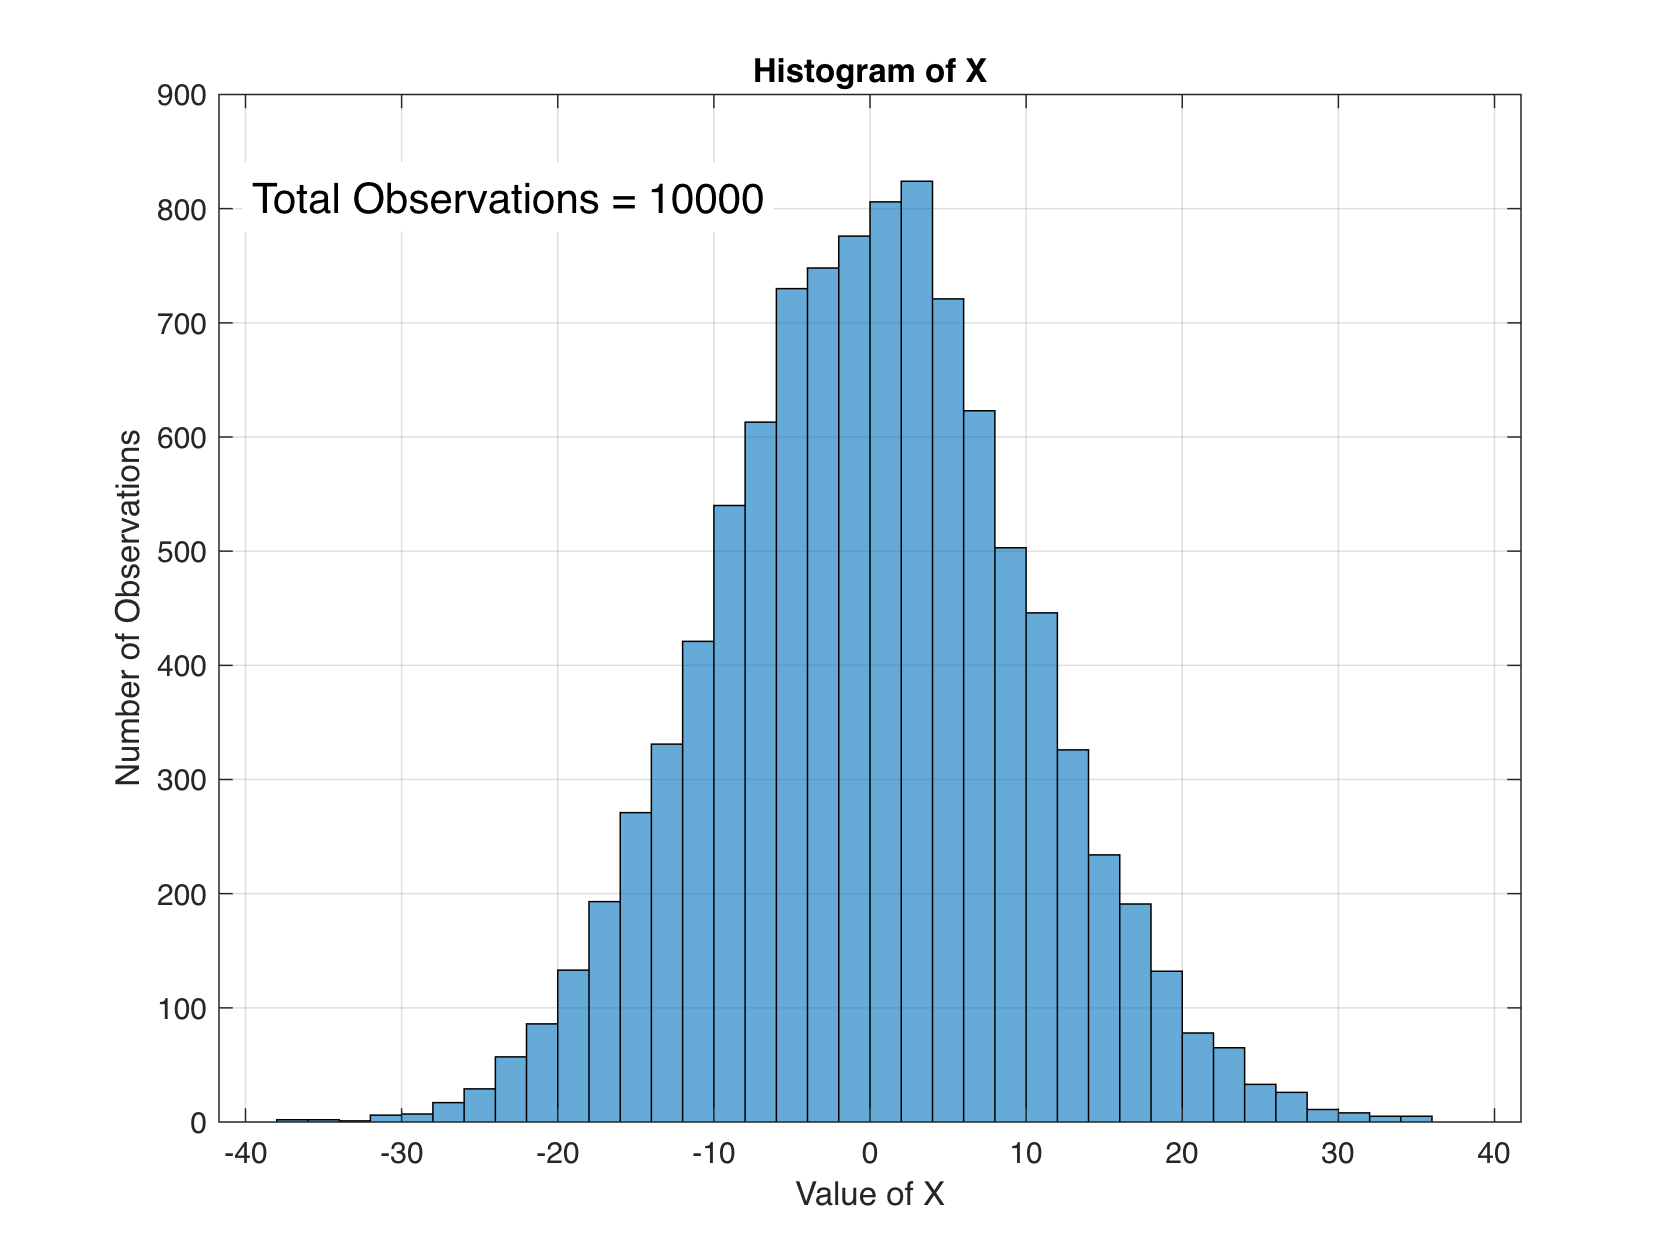

vx = max(abs(xlim));
% 'xlim' (and 'ylim', and 'axis') either report or set axis limits
xlim([-vx vx]); 

In order to make a histogram that looks like a probabilty density function (i.e., it integrates to 1), specify the `Normalization` parameter as `'pdf'`.

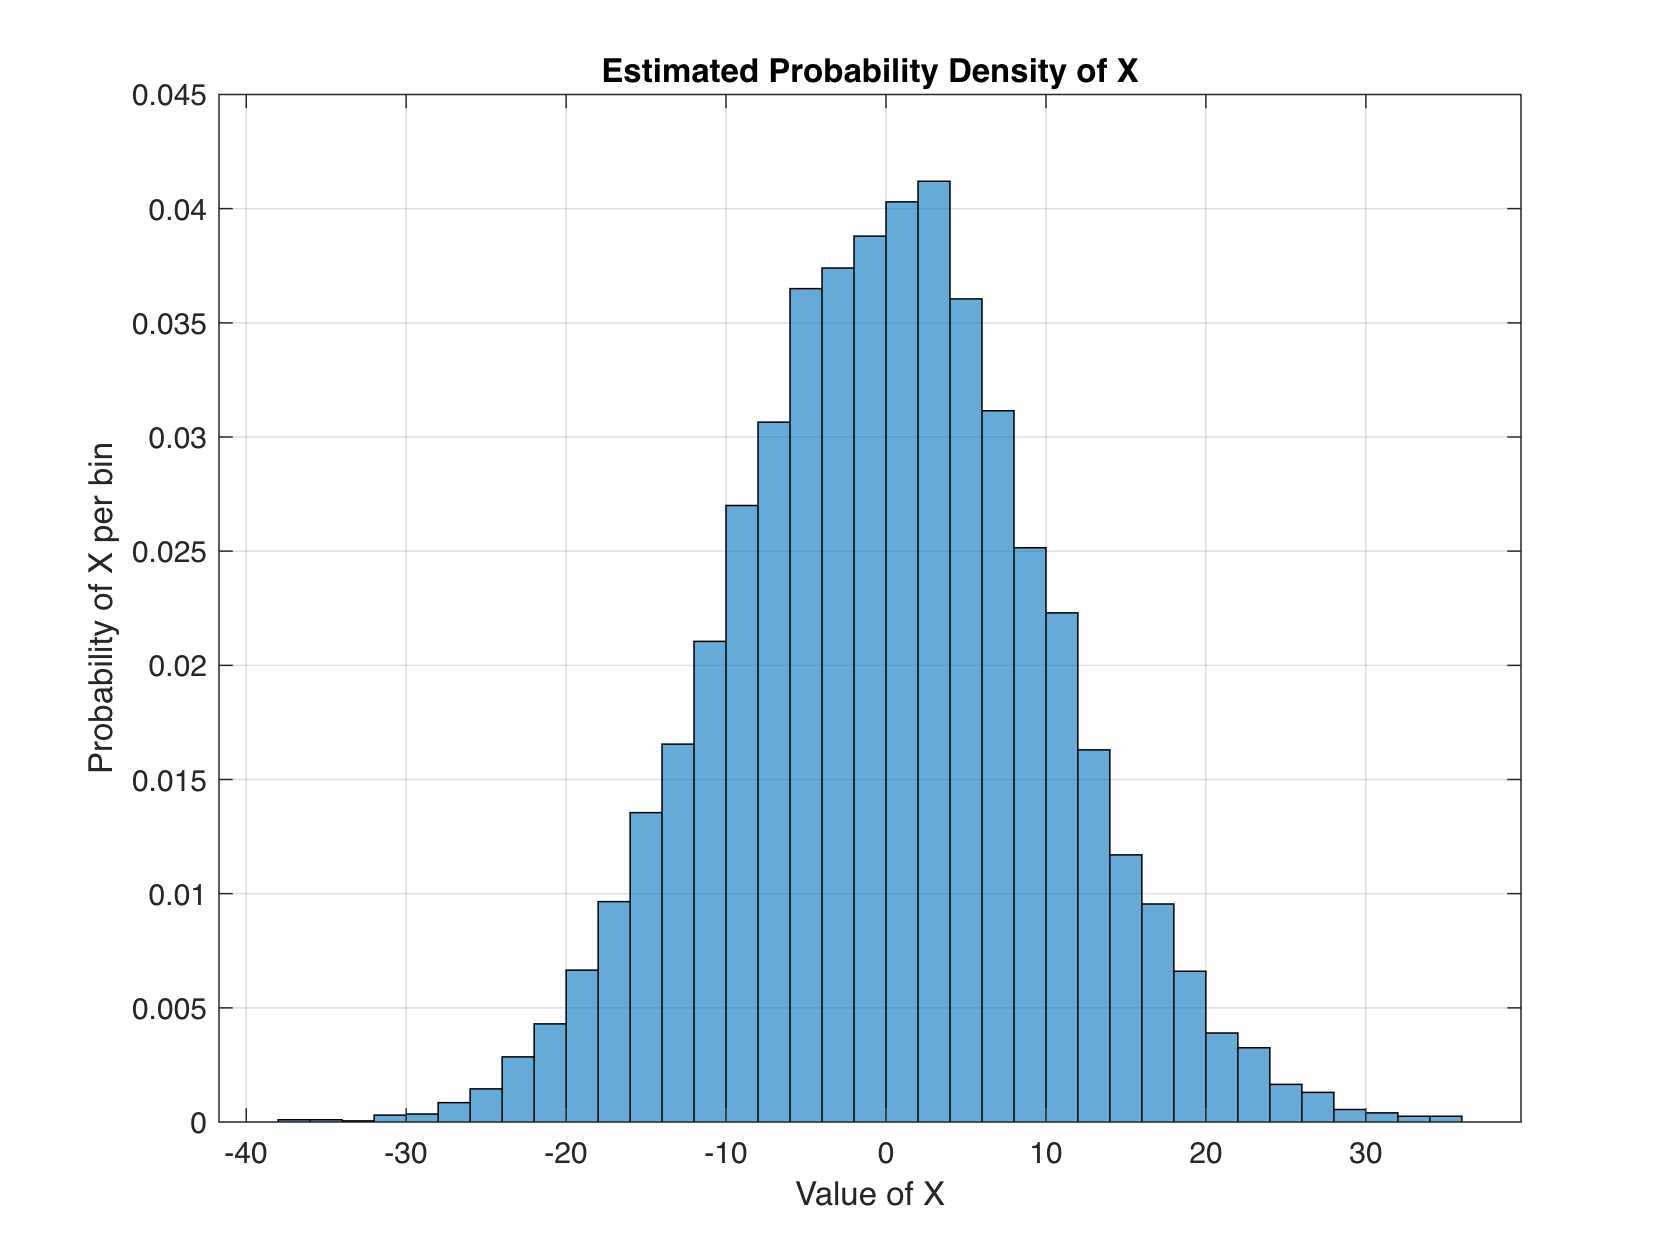

histogram(x,'Normalization','pdf')
xlabel('Value of X')
ylabel('Probability of X per bin')
title('Estimated Probability Density of X')

## Box Plot/Chart

Another common way to visualize both location and variability of data is the box plot (or box and whisker plot). MATLAB has an old function called `boxplot` but the newer `boxchart` is produces nicer figures. Compared to a histogram, it is easier to use a box chart to compare two or more sets of data. 

E.g., 

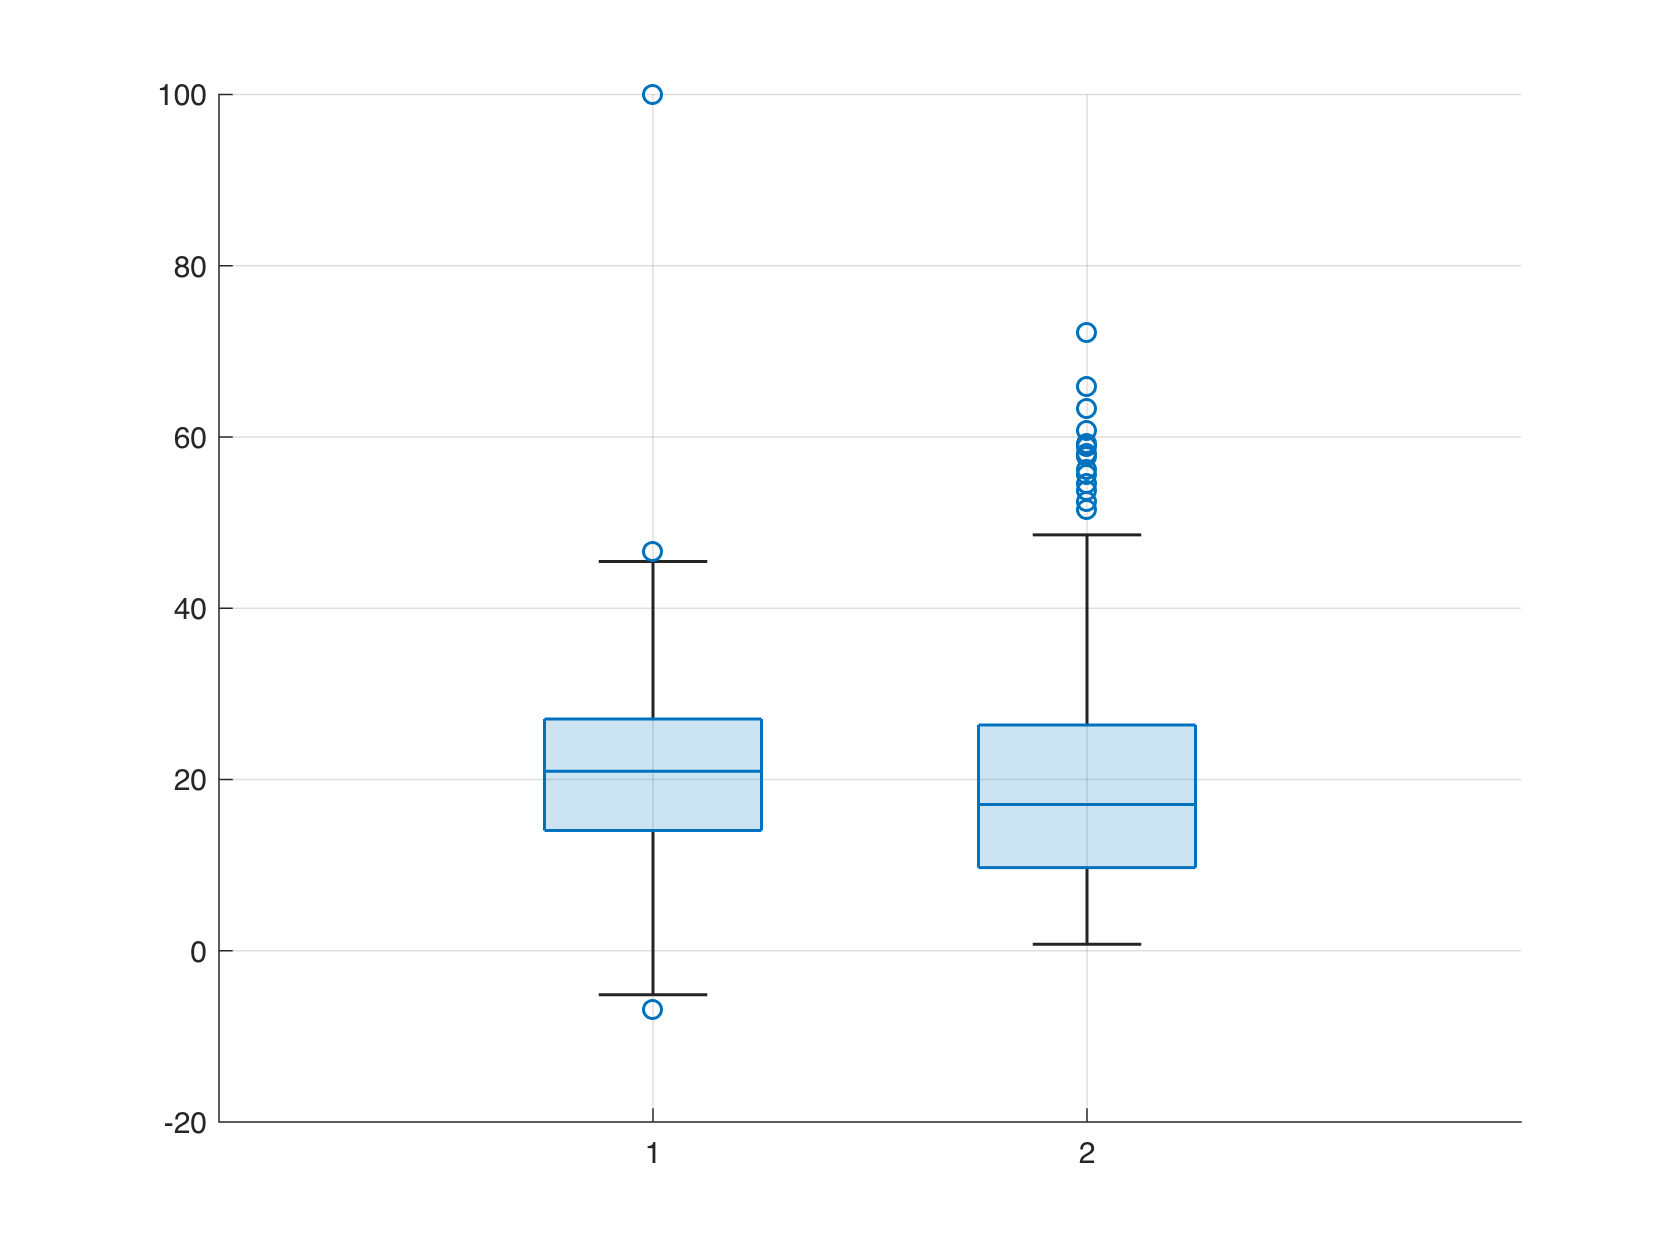

N = 500; 
clear x
m = 20;
s = 10;
x(:,1) = random('Normal',m,s,[N,1]);
x(end,1) = 100; % explicity put in an outlier

k = 2;
t = 10;
x(:,2) = random('gamma',k,t,[N,1]);
b = boxchart(x);

The boxes defines the upper and lower quartiles of the values of $x$ and $y$, and the horizontal line within these regions are the medians. The upper and lower horizontal bars outside the shaded regions define the maximum and minimum values, not including outliers, which are plotted individually as open circles. 

Becase we've created a handle for this plot, we can easily update it's properties after the fact. E.g., try uncommenting either or both lines below and re-run this section.

% b.BoxFaceColor = 'r'; 
% b.Notch = 'on';

## Bar Graphs, Pie Charts, and more ...

% MATLAB has many, many more graphing tools, but for now, look up and read 
% on bar and pie charts -- start with 'help bar', 'help pie'